## Consigna

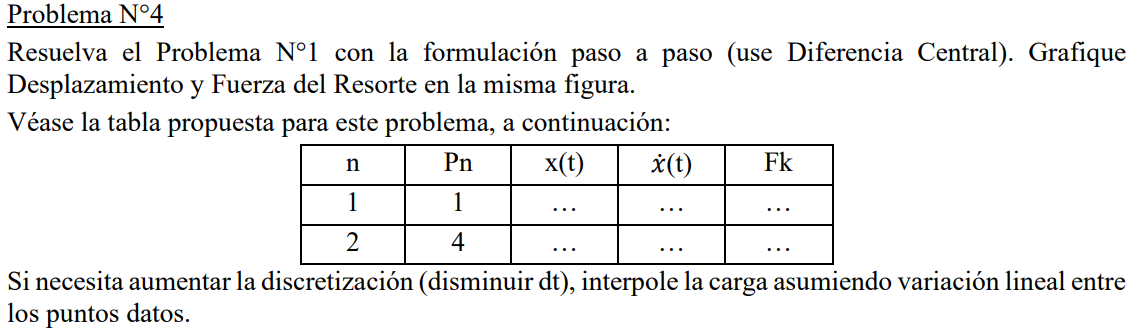

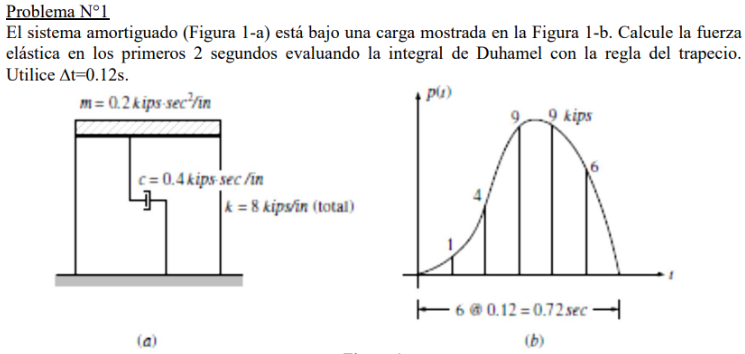

## Respuesta para comparar resultados

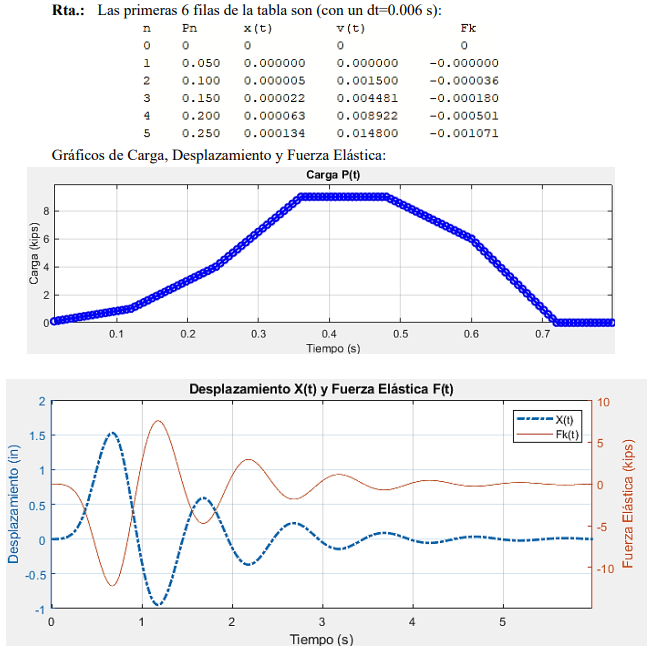

## Resolución por Duhamel para comparar con Newmark Beta

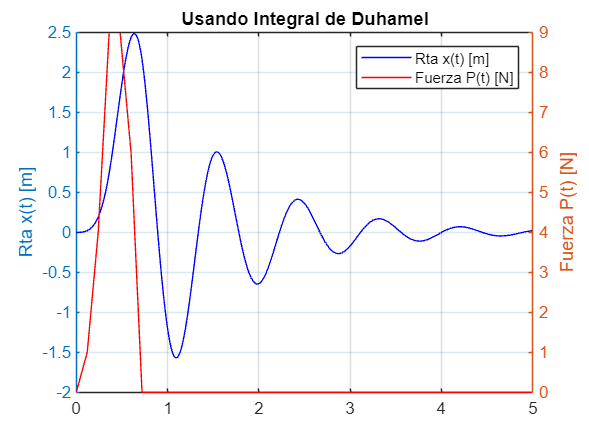

clc; clear;

dt=0.006;
tf=5;
t=0:dt:tf;

e=exp(1);

%% ---------------PARÁMETROS DEL SISTEMA-----------------------
m=0.1;
c=0.2;
k=5;

w=sqrt(k/m);
T=2*pi/w;
zeta=c/(2*m*w);
wd=w*sqrt(1-zeta^2);

%% ------------- DESCRIPCIÓN DE FUERZA EXTERNA ---------------
%Para hacer la fuerza externa, como estoy usando un dt mucho más pequeño,
%tengo que interpolar de forma lineal.

t_discreta = 0:0.12:0.72; %[0, 0.12, 0.24... 0.72] tiempos donde conozco el valor de la fuerza
P_discreta = [0, 1, 4, 9, 9, 6, 0]; %Valores de fuerza conocidos correspondientes a los tiempos de arriba

P = interp1(t_discreta, P_discreta, t,"linear", 0); %con esto creo un vector de long t, donde hago interpolación con los datos discretos. Si me salgo de rango, extrapolo poniendo 0 a los valores de P


%% ------------ CALCULO INTEGRAL DE DUHAMEL ------------------

yc = P.*cos(w*t); %Se usa en la integral duhamel
ys = P.*sin(w*t); %Se usa en la integral de duhamel

A = zeros(1,length(t)); %Se usa en la integral de duhamel
B = zeros(1,length(t)); %Se usa en la integral de duhamel

for i=2:length(t)
    A(i) = A(i-1)*e^(-zeta*w*dt) + dt/(2*w*m) * (yc(i-1)*e^(-zeta*w*dt) + yc(i));
    B(i) = B(i-1)*e^(-zeta*w*dt) + dt/(2*w*m) * (ys(i-1)*e^(-zeta*w*dt) + ys(i));
end

x_duhamel = A.*sin(w*t) - B.*cos(w*t);

figure
title('Usando Integral de Duhamel')
yyaxis left
plot(t,x_duhamel,'b')
ylabel('Rta x(t) [m]')

yyaxis right
plot(t,P,'r');
ylabel('Fuerza P(t) [N]')
legend('Rta x(t) [m]', 'Fuerza P(t) [N]');
grid on


x_duhamel

x_duhamel =          0         0    0.0000    0.0001    0.0002    0.0004    0.0006    0.0010    0.0015    0.0021    0.0029    0.0038    0.0049    0.0062    0.0077    0.0094    0.0114    0.0136    0.0161    0.0188    0.0218    0.0250    0.0286    0.0326    0.0370    0.0418    0.0472    0.0530    0.0594    0.0665    0.0741    0.0825    0.0915    0.1012    0.1117    0.1230    0.1351    0.1480    0.1618    0.1764    0.1919    0.2083    0.2257    0.2440    0.2634    0.2838    0.3054    0.3281    0.3520    0.3772


## Usando Diferencia Central (Método paso a paso)

Para asegurar la estabilidad, se debe verificar que:

donde h en este caso es dt (el paso en el tiempo).

Se puede calcular el desplazamiento y la velocidad en el instante i+1 conociendo los valores en el instante i:

%%---------- CALCULO CON DIFERENCIA CENTRAL (MÉTODO PASO A PASO) -----------

%para lograr la estabilidad, se debe cumplir que dt/T<=1/pi
disp(['dt/t = ',num2str(dt/T)]);

dt/t = 0.0067524


disp(['1/pi = ',num2str(1/pi)]);

1/pi = 0.31831


if dt/T<=1/pi
    disp('Se cumple la condición para asegurar estabilidad por diferencia central');
end

Se cumple la condición para asegurar estabilidad por diferencia central


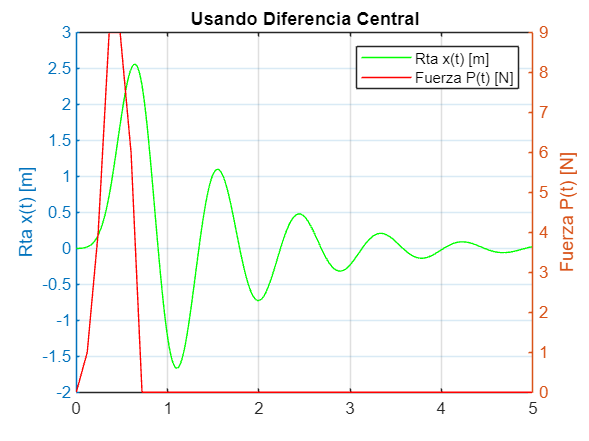


%Inicializo vectores de desplazamiento, velocidad
x=zeros(1,length(t));
dx=zeros(1,length(t));

%Establezco condiciones iniciales
x(1)=0;
dx(1)=0;

%Aplico ecuaciones de Newmark Beta
for i=2:length(t) %ojo, calculo del instante 2 en adelante
    x(i)=x(i-1)+dt*dx(i-1)+(dt^2)*(P(i-1)-c*dx(i-1)-k*x(i-1))/(2*m);
    dx(i)=2*(x(i)-x(i-1))/dt-dx(i-1);
end


figure
yyaxis left
plot(t,x,'g')
ylabel('Rta x(t) [m]')
hold on

yyaxis right
plot(t,P,'r');
ylabel('Fuerza P(t) [N]')
legend('Rta x(t) [m]', 'Fuerza P(t) [N]');
title('Usando Diferencia Central')
grid on

hold off


x

x =          0         0    0.0000    0.0000    0.0001    0.0003    0.0005    0.0008    0.0012    0.0018    0.0025    0.0034    0.0044    0.0056    0.0070    0.0087    0.0105    0.0126    0.0150    0.0176    0.0205    0.0237    0.0271    0.0310    0.0352    0.0399    0.0450    0.0507    0.0569    0.0637    0.0712    0.0793    0.0881    0.0976    0.1079    0.1189    0.1308    0.1435    0.1571    0.1715    0.1868    0.2030    0.2202    0.2383    0.2575    0.2777    0.2991    0.3217    0.3454    0.3704


## Comparación entre Duhamel y Newmark Beta

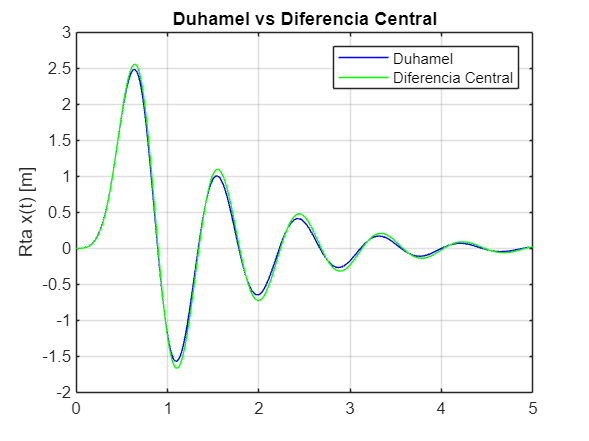

figure
plot(t,x_duhamel,'b',t,x,'g')
title('Duhamel vs Diferencia Central')
ylabel('Rta x(t) [m]')
legend('Duhamel', 'Diferencia Central');
grid on